**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% % load camera parameters
% LoadCameraParameters('./camera_parameters_lab.mat');
% 
% % read the image of the checkerboard
% image = imread('.\test images\checkerboard_lab_rgb.png');

camera = Camera3D('./camera_parameters_lab.mat');

Error using load
'./camera_parameters_lab.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Studium\Documents\GitHub\Robotersysteme_23_24\camera

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in Camera3D (


% define the physical dimensions of a checkerboard square in millimeters.
edgeLength = 30;

% construct the 42 checkerboard points from points 1 and 6 in the rcs
% boardOriginRCS = [282.8  69.4]; % point 1 in rcs
% boardCornerRCS = [280.0 -81.9]; % point 6 in rcs
% boardOriginRCS = [310  76.35]; % point 1 in rcs
% boardCornerRCS = [311.93 -74.62]; % point 6 in rcs
boardOriginRCS = [305.11  82.61]; % point 1 in rcs
boardCornerRCS = [309.18 -68.09]; % point 6 in rcs


% [image, ~] = camera.snapshot();
% imwrite(image, "Testimage.png");

image = imread(".\test images\CaibrationImage.png");

transform = TransformPCStoCCS(image, camera.parameters, edgeLength);

transform.extendToRCS(boardOriginRCS, boardCornerRCS);

% define a set of pixel coordinates for testing
testPointsPCS = [camera.parameters.PrincipalPoint; 
    camera.parameters.PrincipalPoint + 150;
    0 0];

% apply full transformation on the testing set
testPointsRCS = transform.apply(testPointsPCS)
testDistances = norm(testPointsRCS(1, 1:2))

**VISUALIZATION**

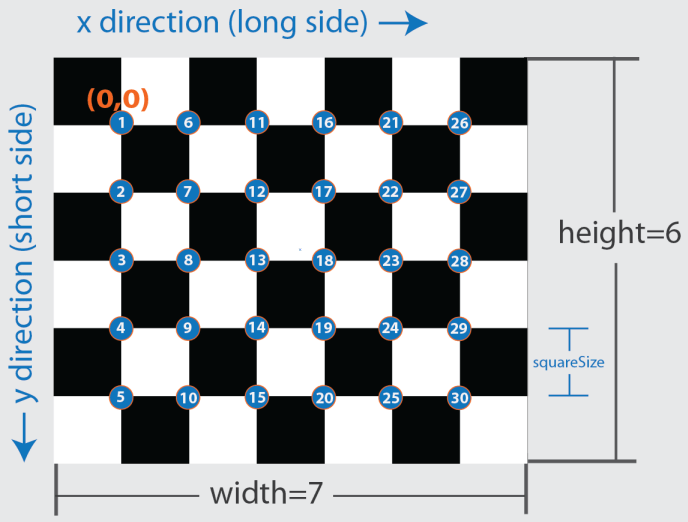

% display the image and plot the detected corners and axes
transform.show(image);